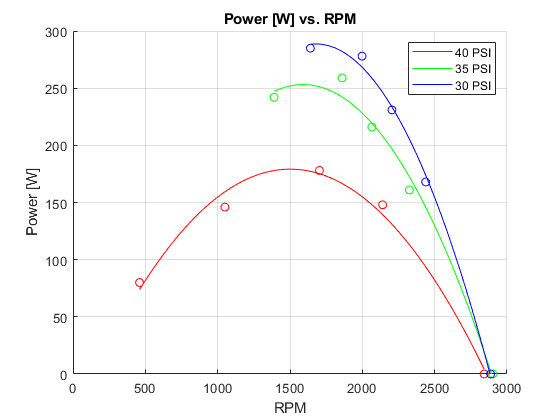

clear;clc

pressure = ["40 PSI", "35 PSI", "30 PSI"];
color = [1 0 0; 0 1 0; 0 0 1];

rpm = [2842,2140,1704,1050,460;
       2902,2325,2066,1860,1390;
       2887,2438,2205,1998,1641;];

power = [0, 148, 178, 146, 80;
         0, 161, 216, 259, 242;
         0, 168, 231, 278, 285;];
   
nu = [0.00, 0.66, 0.80, 0.66, 0.36;
      0.00, 0.26, 0.35, 0.42, 0.39;
      0.00, 0.29, 0.39, 0.47, 0.49;];
%%%
figure
hold on;
for psi = 1:1:numel(pressure)
    powerFit = polyfit(rpm(psi,:), power(psi,:),2);
    x = linspace(min(rpm(psi,:)),max(rpm(psi,:)));
    powerCurv = polyval(powerFit, x);
    powerPlot(psi) = plot(x,powerCurv,'Color',color(psi,:));
    scatter(rpm(psi,:), power(psi,:), 'MarkerEdgeColor',color(psi,:));
end
hold off;
title("Power [W] vs. RPM")
xlabel("RPM")
ylabel("Power [W]")
ylim([0 300])
legend(powerPlot(:), pressure(:))
grid on
saveas(gcf,'ENGR302LAB6POWERvRPM', 'pdf')
saveas(gcf,'ENGR302LAB6POWERvRPM', 'epsc')

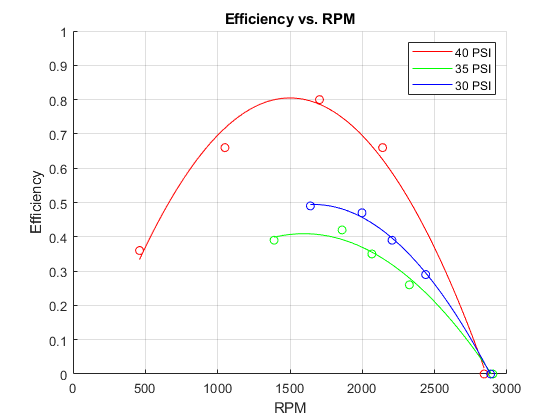

%%%
figure
hold on;
for psi = 1:1:numel(pressure)
    nuFit = polyfit(rpm(psi,:), nu(psi,:),2);
    x = linspace(min(rpm(psi,:)),max(rpm(psi,:)));
    nuCurv = polyval(nuFit, x);
    nuPlot(psi) = plot(x, nuCurv,'Color',color(psi,:));
    scatter(rpm(psi,:), nu(psi,:), 'MarkerEdgeColor',color(psi,:));
end
hold off;
title("Efficiency vs. RPM")
xlabel("RPM")
ylabel("Efficiency")
ylim([0 1])
legend(nuPlot(:), pressure(:))
grid on;
saveas(gcf,'ENGR302LAB6NUvRPM', 'pdf')
saveas(gcf,'ENGR302LAB6NUvRPM', 'epsc')